# Script # 1: Generating of pathloss, shadowing, and Rayleigh fading

Written by Henk Wymeersch, (c) 2019, for the course Wireless Communications (SSY135), Chalmers University of Technology

## Path loss and shadowing

Given a certain transmit power $P_t$, the received power due to pathloss is $P_r = P_t K (d_0/d)^\gamma$, and after pathloss and shadowing in a dB scale $P_r = P_t + K + 10 \gamma \log_10(d_0 /d) + \psi, \psi \sim \mathcal{N}(0,\sigma^2_{\psi}) $. 

Pt=1;                                               % transmit power     
d0=1;                                               % reference distance
d=100;                                              % distance to user
v = 20;                                             % relative velocity in meter per second 
lambda = 0.03;                                       % 0.03 meter wavelength, corresponding to 10 Ghz carrier
K = (lambda / (4*pi*d0))^2;                           
W = 1e6;                                            % bandwidth in Hz (1 MHz)
gamma=3.1;                                          % path loss exponent
sigma2_psi=6.8;                                     % shadowing variance
PL=Pt*K*(d0/d)^gamma;                                  % path loss
SH=10^(0.1*randn(1)*sqrt(sigma2_psi));              % shadowing, converted to linear domain
Pr = PL*SH                                         % average received power after path loss and shadowing

Pr = 2.1863e-12

## Rayleigh fading channel

The Rayleigh fading channel is Gaussian with mean zero and variance given by the power after path loss and shadowing. 

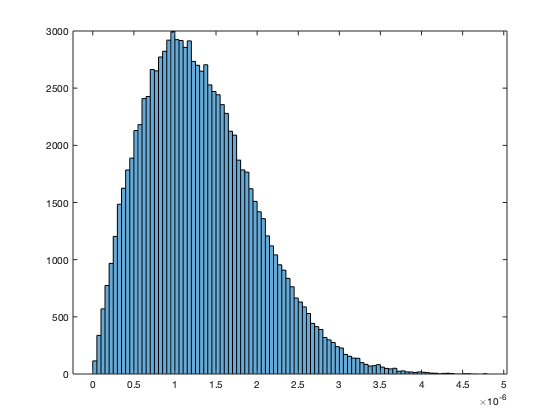

N=100000;                                             % number of channel realizations
h=sqrt(Pr/2)*(randn(1,N)+1j*randn(1,N));            % channel
histogram(abs(h));                                  % should look like a Rayleigh distribution

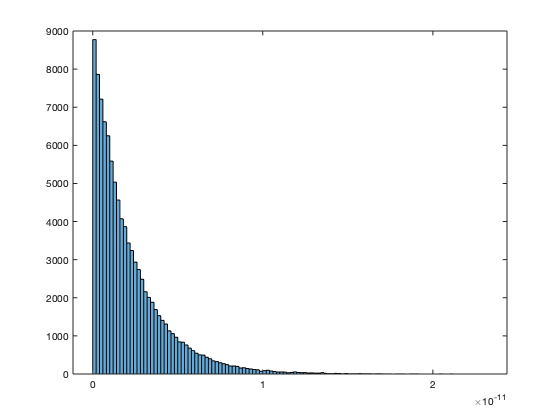

histogram(abs(h).^2);                               % should look like an exponential distribution

% mean(abs(h).^2)                                     % should be equal to Pr

## Rayleigh with mobility

The Rayleigh channel so-far had independent realizations. In practice, the channel varies slowly over time. Suppose we pass the channel through a simple low pass filter. 

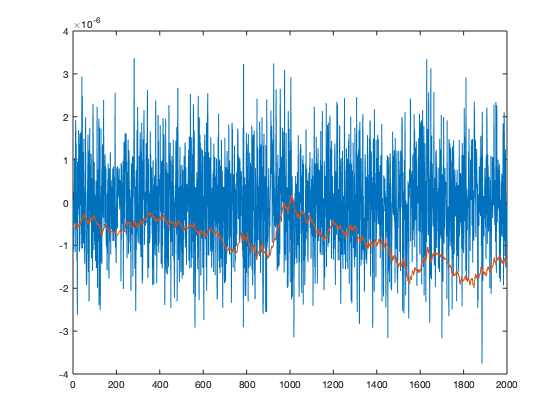

Ts=1/W;                                             % symbol time (1 us)
fD=v / lambda;                                      % Dopler spread in Hz
Ns=round(W/fD);                                      % number of samples in the filter
testFilter=ones(1,Ns)/sqrt(Ns);                     % a simple unit-energy filter (in project: use different filter)
hf=filter(testFilter,1,h);
Np=2000;
plot(1:Np,real(h(Ns/2:Ns/2+Np-1)),1:Np,real(hf(Ns/2:Ns/2+Np-1)))

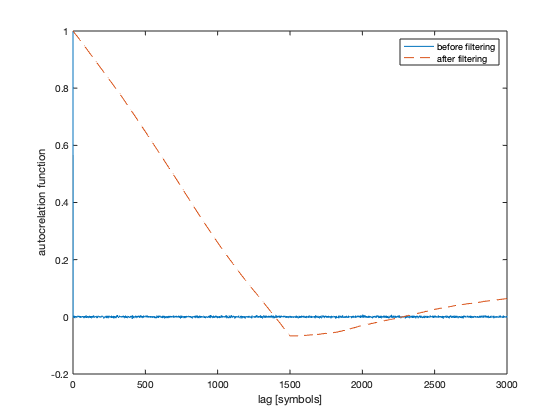

[acf,lags]=autocorr(h,min(2*Ns,length(h)/2));
[acff,lagsf]=autocorr(hf,min(2*Ns,length(h)/2));
plot(lags,acf,lagsf,acff,'--');
xlabel('lag [symbols]')
ylabel('autocrelation function');
legend('before filtering', 'after filtering');

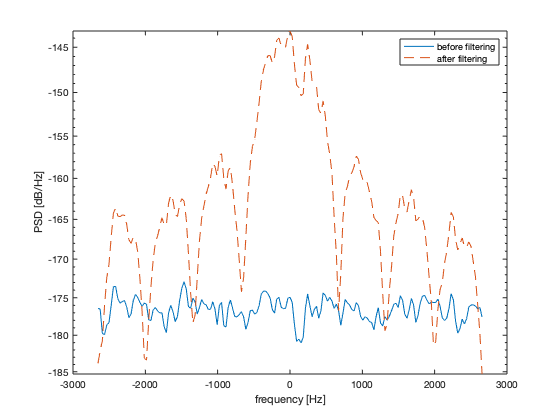

[Pxx,Fr]=pwelch(h,[],[],[],W,'centered');  
[Pxxf,Frf]=pwelch(hf,[],[],[],W,'centered');  
tmp=(abs(Fr)<4*fD);
semilogy(Fr(tmp),10*log10(Pxx(tmp)),Frf(tmp),10*log10(Pxxf(tmp)),'--')
xlabel('frequency [Hz]')
ylabel('PSD [dB/Hz]');
legend('before filtering', 'after filtering');